# Short Project Manipulator

Authors: Pol Puigdemont & Marc Sardà

Team: 11A

Shared link with the teacher: [https://drive.matlab.com/sharing/0eb07338-f0e1-4358-972c-515303b6177b](https://drive.matlab.com/sharing/0eb07338-f0e1-4358-972c-515303b6177b) 

## Introduction

The following file contains our final solution for the manipulator short project.

Between the three given options we have opted for **Option 2.**

The goal of this project is to build a robot environment that can perform tumor surgeries using MATLAB and Peter Corke's Robotics Toolbox. In this project, we have slightly modified the ordering of operations by moving Burning before Trepanation and the questions at the end. This modification was done to ensure that the plot of the environment remains consistent throughout the surgery.

clear
close all
clf

## Environment

In this section we setup the surgery environment: Table, aux Table, Skull and Body, Fiducials, Tumor and Robot. We obtain the corresponding reference frames, all relative to the initial Table.

### Table and auxiliar table

Sets up a 3D environment consisting of a table with four legs and a small auxiliary table. The first part of the code defines the vertices and faces for a cube, which serves as the starting point for the table and legs. The cube is then scaled and translated to create the table and legs with the desired dimensions and positions. Four legs are created by scaling and translating the cube, and the legs are attached to the table by applying transformation matrices to their vertices. Additionally, a small auxiliary table is created using the same process. Finally, the vertices and faces are plotted to visualize the environment in a 3D space.

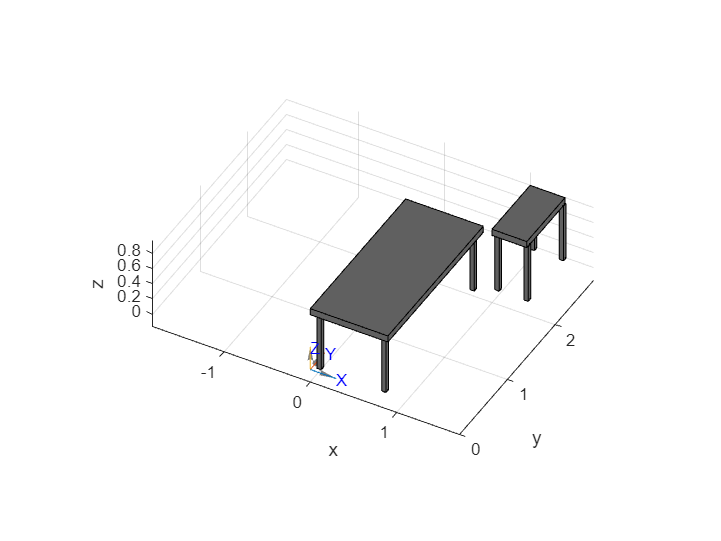

% creates a cube -> starting point for table and legs
v = [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1];
f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];

% scales the cube to compose the surface of the table
H=2;
W=0.9;
D=0.08;
table_height = 0.72;
table_vertices = [W 0 0;0 H 0;0 0 D]*v';
table_vertices = transl(0, 0, table_height) * [table_vertices; ones(1, 8)];

% define the dimensions of a leg and it's offset wrt to the table limits
H_leg = 0.05;
W_leg = 0.05;
D_leg = table_height;
leg_vertices = [W_leg 0 0; 0 H_leg 0; 0 0 D_leg]*v';
leg_vertices = [leg_vertices; ones(1,8)];
leg_offset = 0.05;

% define the dimensions for the small auxiliar table
scale_sH = 0.4;
scale_sW = 0.45;
scale_sD = 1;
small_table_vertices = [scale_sW, 0, 0; 0, scale_sH, 0; 0, 0, scale_sD] * table_vertices(1:3, :);
small_table_vertices = [small_table_vertices; ones(1,8)];

% define transforms
T_Table_U = transl(0,0,0);
T_sTable_Table = transl(+1, 2, 0);
T_l1_U = T_Table_U * transl(leg_offset, leg_offset, 0);
T_l2_U = T_Table_U * transl(W-2*leg_offset, leg_offset, 0);
T_l3_U = T_Table_U * transl(leg_offset, H-2*leg_offset, 0);
T_l4_U = T_Table_U * transl(W-2*leg_offset, H-2*leg_offset, 0);
T_sTable_U = T_Table_U * T_sTable_Table;
T_sl1_U = T_sTable_U * transl(leg_offset*scale_sW, leg_offset*scale_sH, 0);
T_sl2_U = T_sTable_U * transl((W-2*leg_offset)*scale_sW, leg_offset*scale_sH, 0);
T_sl3_U = T_sTable_U * transl(leg_offset*scale_sW, (H-2*leg_offset)*scale_sH, 0);
T_sl4_U = T_sTable_U * transl((W-2*leg_offset)*scale_sW, (H-2*leg_offset)*scale_sH, 0);

% apply transforms
table_U = T_Table_U * table_vertices;
leg1_U = T_l1_U * leg_vertices;
leg2_U = T_l2_U * leg_vertices;
leg3_U = T_l3_U * leg_vertices;
leg4_U = T_l4_U * leg_vertices;
small_table_U = T_sTable_U * small_table_vertices;
sleg1_U = T_sl1_U * leg_vertices;
sleg2_U = T_sl2_U * leg_vertices;
sleg3_U = T_sl3_U * leg_vertices;
sleg4_U = T_sl4_U * leg_vertices;

% display
figure
hold on
patch('Vertices',table_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor', '#606060','FaceAlpha',1)
patch('Vertices',leg1_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','#606060','FaceAlpha',1)
patch('Vertices',leg2_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','#606060','FaceAlpha',1)
patch('Vertices',leg3_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','#606060','FaceAlpha',1)
patch('Vertices',leg4_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','#606060','FaceAlpha',1)
patch('Vertices',small_table_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','#606060','FaceAlpha',1)
patch('Vertices',sleg1_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','#606060','FaceAlpha',1)
patch('Vertices',sleg2_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','#606060','FaceAlpha',1)
patch('Vertices',sleg3_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','#606060','FaceAlpha',1)
patch('Vertices',sleg4_U(1:3,:)','Faces',f,'FaceVertexCData',hsv(6),'FaceColor','#606060','FaceAlpha',1)
grid on
xyzlabel
axis equal
xlim([-1.83 1.73])
ylim([0.00 2.81])
zlim([-0.162 0.962])
view([-331.059 39.491])
trplot(T_Table_U,'framelabel','B' ,'color', 'blue','arrow','length', 0.3)

### Body

Loads a 3D human body model from a MATLAB data file and computes its dimensions. It then defines a transformation matrix `T_B_U` to position and orient the human body on a table. The transformed human body is visualized as a patch with yellow frame and translucent yellow color.

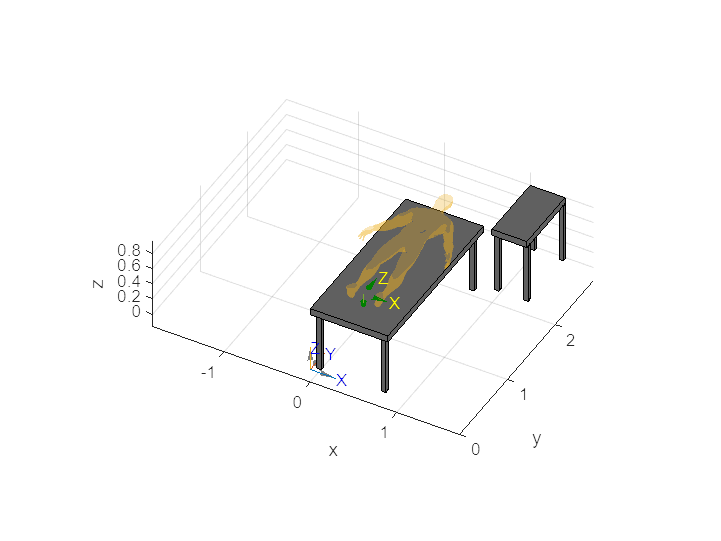

human = load('F_V_HumanBody.mat');
human_scale = 1;
x_max = max(human.Vh(:,1));
y_max = max(human.Vh(:,2));
z_max = max(human.Vh(:,3));
x_min = min(human.Vh(:,1));
y_min = min(human.Vh(:,2));
z_min = min(human.Vh(:,3));
height_human = z_max-z_min;
widht_human = x_max-x_min;
depth_human = y_max-y_min;
T_B_U=T_Table_U*transl(0,0,table_height)*transl([W/2 0.3 D+depth_human/2])*trotx(-pi/2);
human_U = (T_B_U * [human_scale*human.Vh'; ones(1, length(human.Vh))])';
patch('Vertices', human_U(:, 1:3), 'Faces', human.Fh, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
trplot(T_B_U,'framelabel','B' ,'color', 'yellow','arrow','length', 0.3)

### Skull & Box

Loads a 3D model of a skull from a file and computes its dimensions. It then places the skull on a table and displays it in a 3D plot using MATLAB's `patch` function. Additionally, it defines a box representing the Image regions of the Dicom Images that surrounds the skull and displays it as well. The code sets the position and orientation of the skull and box with respect to the table using transformation matrices. By aligning the box with the skull model in the correct orientation, the positions of the anatomical structures can be accurately determined and mapped onto the image coordinates. This allows for precise localization and targeting of specific regions during medical procedures.

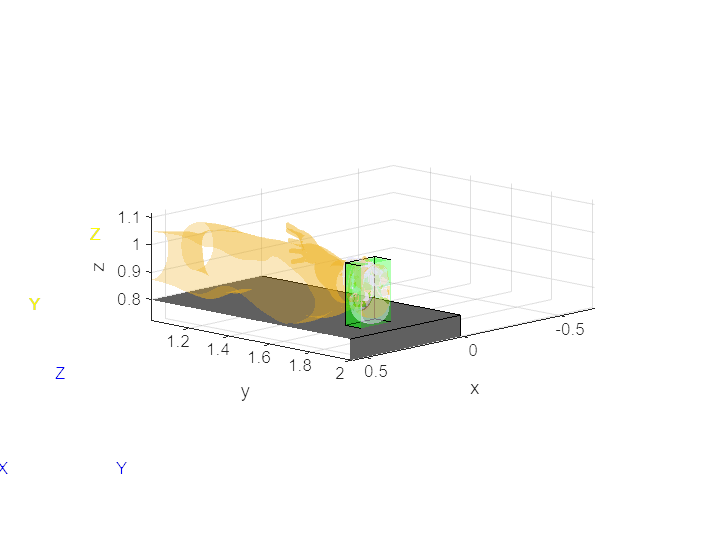

skull = load('F_V_Skull.mat');
skull_scale = 1;
skull_x_max = max(skull.Vs(:,1));
skull_x_min = min(skull.Vs(:,1));
skull_y_max = max(skull.Vs(:,2));
skull_y_min = min(skull.Vs(:,2));
skull_z_max = max(skull.Vs(:,3));
skull_z_min = min(skull.Vs(:,3));
height_skull = skull_z_max-skull_z_min;
width_skull = skull_x_max-skull_x_min;
depth_skull = skull_y_max-skull_y_min;
T_S_U=T_Table_U*transl(W/2,1.88,table_height+height_skull+0.015)*trotx(-pi/2);
skull_U = T_S_U*[skull_scale*skull.Vs'; ones(1,length(skull.Vs))];

xoffset = 0.007;
yoffset = 0.01925;
T_Box_U = T_S_U*transl(width_skull/2,-depth_skull/2, height_skull)*troty(pi/2)*trotx(-pi/2)*transl(0,-xoffset,-yoffset);
box_S=[width_skull 0 0;0 depth_skull 0;0 0 3*height_skull/4]*v';
box_S(4,:)=1;
box_U=T_Box_U*trotz(pi/2)*trotx(pi/2)*transl(xoffset, yoffset, 0)*box_S;
box_U_plot = box_U';
skull_U_plot = skull_U';

% Display the box
patch('Vertices', box_U_plot(: ,1:3), 'Faces', f, ...
    'FaceVertexCData', hsv(6), ...
    'FaceColor', 'g', ...
    'FaceAlpha',0.3);

% Display Skull
patch('Vertices', skull_U_plot(:, 1:3), 'Faces', skull.Fs, ...
    'FaceColor', '#E6E6FA', ...
    'FaceAlpha', 0.5, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);

xlim([-0.68 0.57])
ylim([1.02 2.01])
zlim([0.723 1.117])
view([-226.357 11.925])

% trplot(T_S_U,'framelabel','B' ,'color', 'blue','arrow','length', 0.3)

### Fiducials and Tumor

Defines the positions of three fiducials, labeled as F1, F2, and F3, that are used during brain surgery to help guide the surgeon. The fiducials are represented by small spheres in the 3D coordinate system. It also displays a red ball that represents the position of a tumor in the patient's brain. Then, defines some parameters related to the size and position of the fiducials and the tumor. Last, it calculates the positions of the fiducials and the tumor relative to this frame of reference using the parameters and some simple geometric calculations.

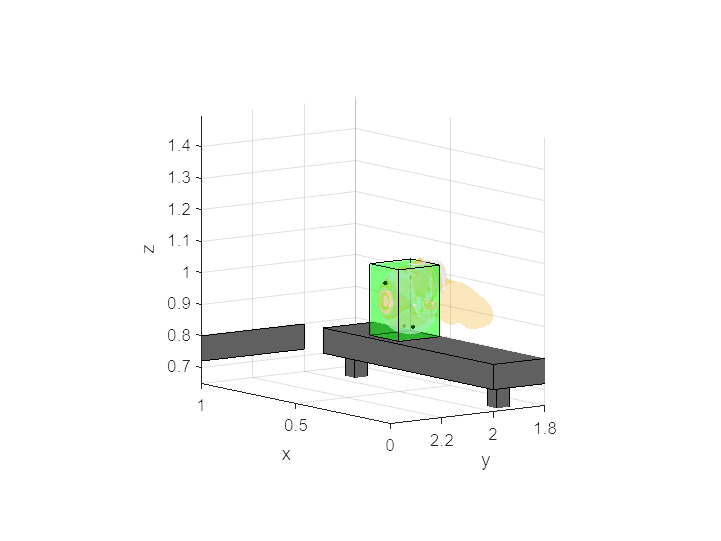

r=0.015; % 5 mm;
rf=0.0055;
% De la mesa a la skull
OpT = T_Table_U(1:3,4);
TransXskull = W/2+OpT(1);
TransYskull = 1.88+OpT(2);
TransZskull = table_height+height_skull+0.015+OpT(3);
% De la skull a la ref frame Box
TransXBoxAx = TransXskull+width_skull/2;
TransYBoxAx = TransYskull+depth_skull;
TransZBoxAx = TransZskull + height_skull/2;
% De la ref frame Box a esquina caja
TransXBox = TransXBoxAx;
TransYBox = TransYBoxAx-r;
TransZBox = TransZBoxAx + r*3/4;
% Obtenemos tumor y fiduncials de la esquina Box a punto colocacion a partir de las dicom images
F1 = [TransXBox-width_skull*0.1666,TransYBox-0.7143*height_skull*3/4,TransZBox-0.92*depth_skull];
F2 = [TransXBox-width_skull*0.89,TransYBox-0.42*height_skull*3/4,TransZBox-0.85*depth_skull];
F3 = [TransXBox-width_skull*0.43,TransYBox-0.07*height_skull*3/4,TransZBox-0.255*depth_skull];
r2 = 0.002;
R_c = 0.01;
color = [1 0 0];
ANGLES = [];
dist = [];
% draw F1, F2, F3
[X,Y,Z] = sphere;
surf(X*rf + F1(1),Y*rf + F1(2),Z*rf + F1(3),'FaceColor',[1 0 0])
[X,Y,Z] = sphere;
surf(X*rf + F2(1),Y*rf + F2(2),Z*rf + F2(3),'FaceColor',[1 0 0])
[X,Y,Z] = sphere;
surf(X*rf + F3(1),Y*rf + F3(2),Z*rf + F3(3),'FaceColor',[1 0 0])
axis([0 1 1.8 2.4 0.65 1.5])
view([233.667 9.066])

### Robot

Sets the robot's position and orientation, and visualizes it in a 3D workspace. The robot's position is calculated by multiplying its translation with respect to the table frame by the table frame's transformation matrix. Then, the PUMA 560 robot is visualized.

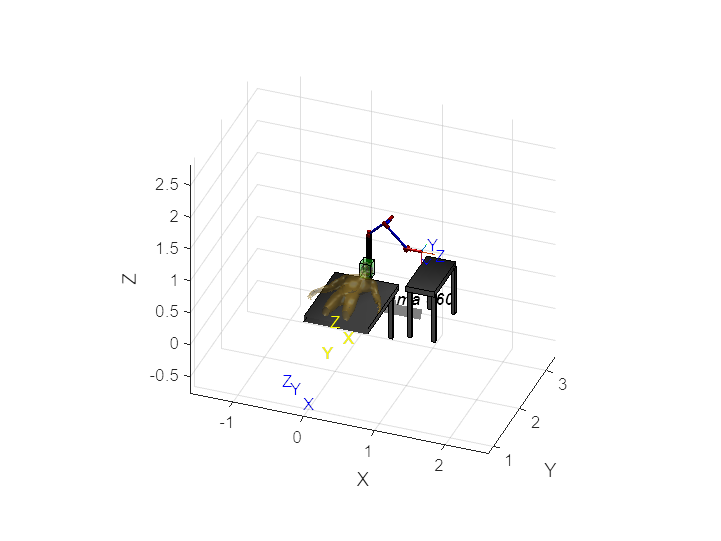

robot_translation = T_Table_U*transl(0.2,2.75,1);
mdl_puma560
p560.base=robot_translation;
T_R_U=p560.base.T;
p560.tool=transl(0,0,0.2);
p560.plot(qn,'zoom',2.5,'workspace', [-1.3 1.7 1.5 3 0 1.5],'view',[20 20], 'notiles')
xlim([-1.61 2.61])
ylim([0.83 3.37])
zlim([-0.76 2.83])
view([20.57 32.36])

## Transforms

Following the same reasoning as in the second approach solution. We will explore the process of calculating the transformation matrix T_I_R that allows us to locate the tumor in the universe reference frame using the fiducial positions in the image and universe reference frames. This involves a series of coordinate transformations and calculations, including finding the fiducials in the image reference frame, transforming them to the universe reference frame, and ultimately calculating the transformation matrix T_I_R. These transformations are essential for the success of the tumor surgery as they enable the robot to accurately locate and remove the tumor.

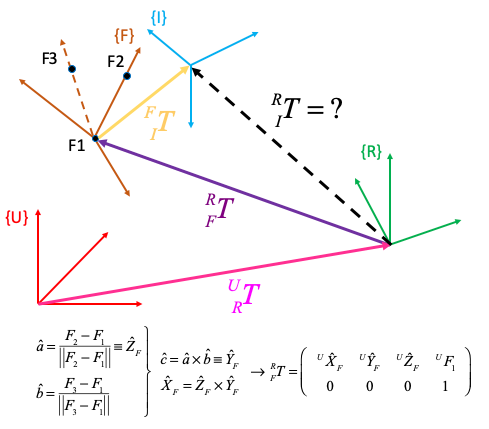

### Fiducial points in Robot Frame

Using ${}^BP = {}_B^A{T^{ - 1}}{}^AP$ calculates the coordinates of the fiducial points in the robot frame. This is done by taking the inverse of the transformation matrix T_R_U, which gives us the transformation from the universe frame to the robot frame.

Fi_R=inv(T_R_U)*[F1' F2' F3';ones(1,3)];

### Fiducials wrt to Robot Reference Frame

Calculates the reference frame of the fiducial points with respect to the robot reference frame. First, the direction of the y-axis of the fiducial reference frame, `Yf`, is calculated as the normalized vector pointing from the first to the second fiducial point. The direction of the z-axis, `Zf`, is calculated by taking the cross product of `Yf` with the vector pointing from the first to the third fiducial point and normalizing the result. Finally, the x-axis, `Xf`, is calculated as the cross product of `Yf` and `Zf`, and normalized. The resulting reference frame, `T_F_R`, is a homogeneous transformation matrix that represents the transformation from the fiducial reference frame to the robot reference frame. It is constructed by placing the x-, y-, and z-axis vectors in the first three columns of the matrix, and the position vector of the first fiducial point in the fourth column.

% fiducials reference frames
Yf = (Fi_R(1:3,2)-Fi_R(1:3,1))/norm(Fi_R(1:3,2)-Fi_R(1:3,1));
b=(Fi_R(1:3,3)-Fi_R(1:3,1))/norm(Fi_R(1:3,3)-Fi_R(1:3,1));
Zf = cross(Yf,b)/norm(cross(Yf,b));
Xf = cross(Yf,Zf)/norm(cross(Yf,Zf));
T_F_R = [[Xf;0] [Yf;0] [Zf;0] [Fi_R(:,1)]];

### Fiducials wrt to Universe Reference Frame

Calculates the transformation matrix T_F_U, which gives the position and orientation of the fiducial frame with respect to the universe frame. T_F_R is the transformation matrix that gives the position and orientation of the fiducial frame with respect to the robot frame, which is obtained by calculating the unit vectors along the x, y, and z axes of the fiducial frame with respect to the robot frame. Then, the transformation matrix T_F_U is obtained by multiplying T_F_R with T_R_U.

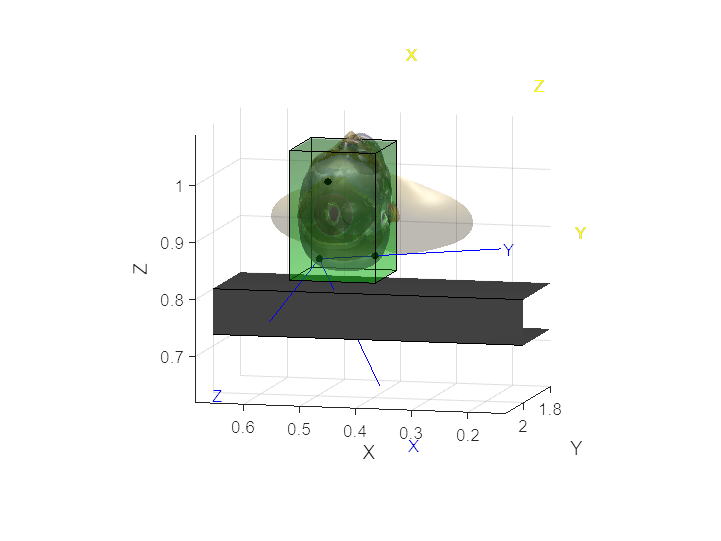

T_F_U=T_R_U*T_F_R;
trplot(T_F_U,'Frame','F','color', 'b','length',0.4)
xlim([0.132 0.685])
ylim([1.799 2.131])
zlim([0.619 1.089])
view([193.530 8.406])

### Fiducials wrt to image frame

Calculates the fiducial points with respect to the image frame. The coordinates of the fiducial points are obtained from the DICOM images, and are denoted as F1D, F2D, and F3D. Using these coordinates, the orientation of the fiducial points in the image reference frame is calculated, which is represented by a rotation matrix T_F_I. The rotation matrix is constructed from three orthogonal unit vectors XfD, YfD, and ZfD, which define the orientation of the fiducial points with respect to the image reference frame, and a translation vector F1D.

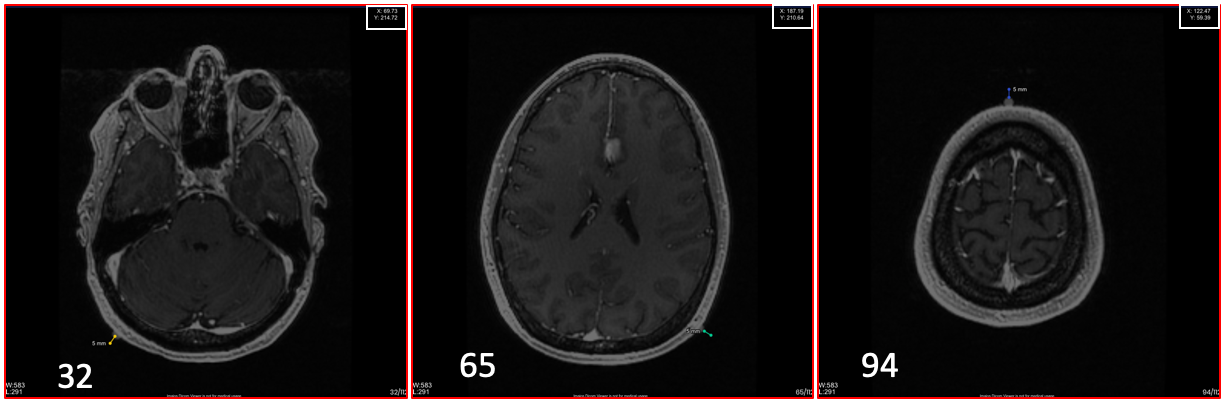

% fiducial coordinates wrt to image from Dicom Images
pitch =1.4; % Pitch among slices 
F1D = [0.06973 0.21496 0.032*pitch]'; %image #32
F2D = [0.18743 0.21088 0.065*pitch]'; %image #65
F3D = [0.12295 0.05915 0.094*pitch]'; %image #94

% fiducials wrt to image reference frame
YfD = (F2D-F1D)/norm(F2D-F1D);
bD = (F3D-F1D)/norm(F3D-F1D);
ZfD = cross(YfD,bD)/norm(cross(YfD,bD));
XfD = cross(YfD,ZfD)/norm(cross(YfD,ZfD));
T_F_I = [[XfD;0] [YfD;0] [ZfD;0] [F1D;1]];

### Image wrt to Universe

Calculates the transformation matrix T_I_U, which represents the pose of the image coordinate system in the universe coordinate system. It is computed by multiplying the transformation matrix T_F_U (which represents the pose of the fiducial coordinate system in the universe coordinate system) by the inverse of the transformation matrix T_F_I (which represents the pose of the fiducial coordinate system in the image coordinate system).

T_I_U=T_F_U*inv(T_F_I);

### Image wrt to Robot

Calculates the homogeneous transformation matrix T_I_R, which represents the pose of the image reference frame with respect to the robot reference frame. It does this by multiplying the inverse of the robot-to-universe transformation matrix T_R_U, the fiducials-to-universe transformation matrix T_F_U, and the inverse of the fiducials-to-image transformation matrix T_F_I.

T_I_R=inv(T_R_U)*T_F_U*inv(T_F_I);

### Tumor Center Obtention

Calculates the position of the tumor center in the robot and universe reference frames using the transformation matrix T_I_R and the coordinates of the tumor center in the image frame (TD). It also calculates the position of the tumor center in the universe frame using the transformation matrices T_R_U and T_I_R. The pitch variable represents the distance between two consecutive slices in the DICOM images.

pitch =1.4; % Pitch among slices 
TD = [0.132 0.097 0.077*pitch]'; %image #77 (centre del tumor)

Tumor_i_R=T_I_R*[TD; 1];
Ti_U=T_R_U*T_I_R*[TD;1];

## Biopsy

In the biopsy section, we will use the obtained tumor center to plan the needle insertion and perform the actual biopsy procedure.

### Environment

Sets up the environment for the biopsy simulation. It defines the robot tool. It also draws the tumor and the three biopsy needles using the sphere function.

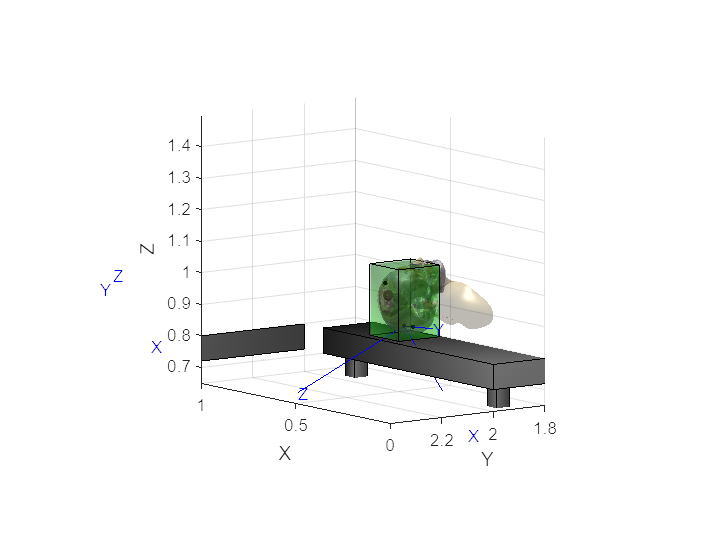

p560.tool=transl(0.05, 0 ,0.25);
axis([-0.15 2 0 5 0 2.5])

% we draw the tumor in the calculated point
[X,Y,Z] = sphere;
surf(X*r + Ti_U(1),Y*r + Ti_U(2),Z*r + Ti_U(3),'FaceColor',[1 1 1],'FaceAlpha',0.2, 'EdgeAlpha',0.2)
% draw de fiducials
[X,Y,Z] = sphere;
surf(X*rf + F1(1),Y*rf + F1(2),Z*rf + F1(3),'FaceColor',[1 0 0])
[X,Y,Z] = sphere;
surf(X*rf + F2(1),Y*rf + F2(2),Z*rf + F2(3),'FaceColor',[1 0 0])
[X,Y,Z] = sphere;
surf(X*rf + F3(1),Y*rf + F3(2),Z*rf + F3(3),'FaceColor',[1 0 0])
axis([0 1 1.8 2.4 0.65 1.5])
view([233.667 9.066])

### Movement

This section of code sets up a movement trajectory for the robot to perform the biopsy. Initially, the robot moves quickly from its initial position to a location horizontally away from the tumor. Later, the robot moves slowly from this horizontal location to the position where the tumor is located, moving along the Z-axis of the end effector. The specific movements are achieved through the use of various functions, including jtraj for joint space trajectory, ctraj for Cartesian trajectory, and ikine and fkine for inverse and forward kinematics, respectively. The final trajectory is stored in the variable QT, and the plot is viewed from a specific angle using the view function.

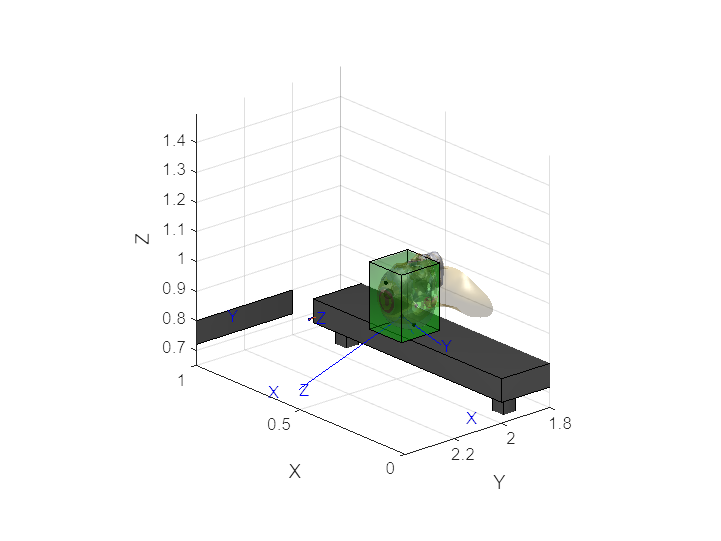

T0=p560.fkine(qr);
INI = transl(Ti_U(1:3));
T1 = INI*transl(0,0.5,0)*trotx(pi/2)*trotz(-pi/2);
T2 = INI*trotx(pi/2)*trotz(-pi/2);
t_0=linspace(0,3,30);% trajectory time
q_0 = p560.ikine6s(T0,'run'); 
q_1 = p560.ikine6s(T1,'run');
Q_0=jtraj(q_0,q_1,t_0);
p560.plot(Q_0);
t_1=linspace(0,1,100);
S=tpoly(0,1,t_1);
T_1_2 = ctraj(T1,T2,S);
Q_1 = p560.ikine6s(T_1_2);
QT=[Q_0;Q_1];
view([229.016 21.616])

### Video

% p560.plot(QT,'view',view([229.016 21.616]), 'zoom',9,'workspace', [-1 0.5 -0.5 0.5 -1 1],'trail','-','jaxes','movie','biopsy_video.mp4')

## Burning

The burning operation involves the use of a probe to burn a small portion of the tissue surrounding the biopsy site. This process helps to ensure that any cancerous cells in the area are destroyed. In the following section, we will see how the burning operation is simulated.

### Environment

The code sets up the environment for the burning operation. It defines the robot tool and displays the tumor and biopsy needles using the sphere function. The view function sets the viewing angle of the display.

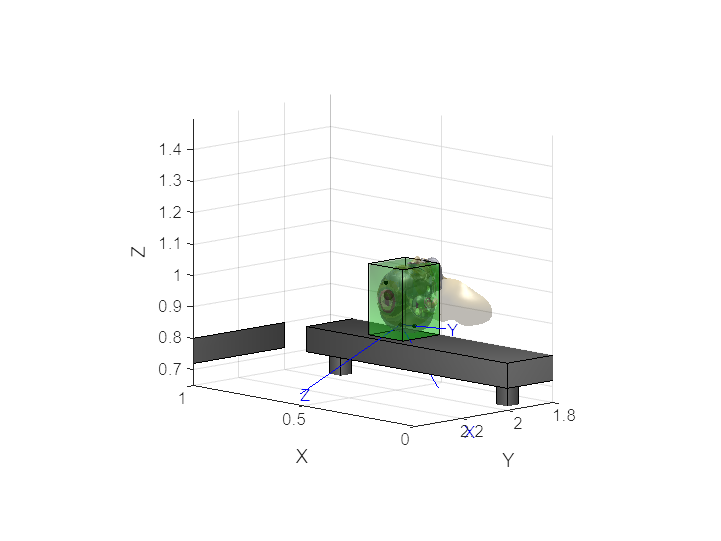

p560.tool=transl(0, 0, 0.2);
p560.plot(qr,'zoom',8)% RTB;

%%% tumor %%%5
[X,Y,Z] = sphere;
surf(X*r + Ti_U(1),Y*r + Ti_U(2),Z*r + Ti_U(3),'FaceColor',[1 1 1],'FaceAlpha',0.2, 'EdgeAlpha',0.2);
%%% F1 %%%
[X,Y,Z] = sphere;
surf(X*rf + F1(1),Y*rf + F1(2),Z*rf + F1(3),'FaceColor',[1 0 0]);
%%% F2 %%%
[X,Y,Z] = sphere;
surf(X*rf + F2(1),Y*rf + F2(2),Z*rf + F2(3),'FaceColor',[1 0 0]);
%%% F3 %%%
[X,Y,Z] = sphere;
surf(X*rf + F3(1),Y*rf + F3(2),Z*rf + F3(3),'FaceColor',[1 0 0]);

view([225.763 10.266])

### Movement

We want to create mini-spheres around the tumor, which is a sphere with a radius of 15mm. To create the mini-spheres, we use a triple loop that creates spheres of size 2mm within a 30 x 30 x 30 mm³ cube. These mini-spheres are created in the same space as the tumor, so only the mini-spheres that are within the tumor's limits are considered. Therefore, we only consider the mini-spheres that are on the tumor's surface. The center of each mini-sphere is calculated as a translation with respect to the tumor's center, so the origin of each mini-sphere depends on the origin of the tumor. If the distance between the center of a mini-sphere and the center of the tumor is less than the tumor's radius, the mini-sphere is within the limits and is selected. For each mini-sphere, we calculate the vector that connects its center with the robot's end-effector center. We also calculate the angles in the x, y, and z directions between this vector and the vector 'VO,' which connects the end-effector with the center of the tumor. These angles are used to determine the rotations that we need to perform for each mini-sphere such that the end-effector's z-axis points toward the center of the mini-sphere. We also save the distance of each mini-sphere from the end-effector since we will consider it for the order in which we approach the mini-spheres. Finally, we plot each mini-sphere in the space and store it in a list called ESFERAS.

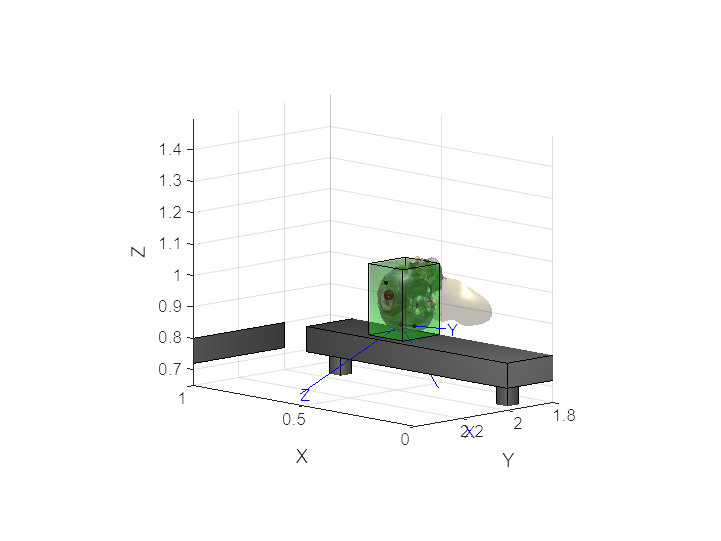

r2 = 0.002;
p1 = T1(1:3,4);
ESFERAS = [];
for i=(-r/r2+1):r/r2
    for j=(-r/r2+1):r/r2
        for z=(-r/r2+1):r/r2
            disp_x = r2*(i-1)*2+r2+Ti_U(1);
            disp_y = r2*(j-1)*2+r2+Ti_U(2);
            disp_z = r2*(z-1)*2+r2+Ti_U(3);
            if sqrt(abs(disp_x-Ti_U(1))^2 + abs(disp_y-Ti_U(2))^2+abs(disp_z-Ti_U(3))^2) + r2 <= r
                p2 = [disp_x, disp_y, disp_z];
                V0 = Ti_U(1:3)'-p1';
                VN = p2-p1';
                VNx  = VN;
                VNx(3) = V0(3);
                CosTheta = max(min(dot(VNx,V0)/(norm(VNx)*norm(V0)),1),-1);
                angleX = real(acosd(CosTheta));
                CosTheta = max(min(dot(VNx,VN)/(norm(VNx)*norm(VN)),1),-1);
                angleY = real(acosd(CosTheta));
                ANGLES = [ANGLES; deg2rad(angleX) deg2rad(angleY)];
                dist = [dist, norm(VN)];
                pl = surf(X*r2+disp_x,Y*r2+disp_y,Z*r2+disp_z,'FaceColor',color, 'FaceAlpha',1, 'EdgeAlpha',0.0);
                ESFERAS = [ESFERAS; pl];
            end
        end
    end
end

After computing the angles for each mini-sphere, we calculate the pose of the end-effector for each mini-sphere. We then move the end-effector from the pose of the prev mini-sphere to the pose of the new mini-sphere. The order in which we move the end-effector is based on the distance of the mini-sphere from the center of the end-effector, with the farthest sphere moved first. We use the jtraj function to calculate a trajectory between the prev and new poses and then use the ctraj function to generate intermediate poses between those two poses. We then use the inverse kinematics function (ikine6s) to compute the joint angles for each intermediate pose. The resulting joint angles are added to a list of "burn" joint angles that will be used to move the robot to the final position. Finally, the pose of the new mini-sphere becomes the prev pose for the next iteration, and we repeat the process for the remaining mini-spheres.

T0=p560.fkine(qr);
t_0=linspace(0,3,30);% trajectory time
q_0 = p560.ikine6s(T0,'run'); 
q_1 = p560.ikine6s(T1,'run');
Q_0_Burn=jtraj(q_0,q_1,t_0);
s = size(dist);
n = s(2);
prev = T1;
Burn = [Q_0_Burn];
t_1=linspace(0,1,50);
S=tpoly(0,1,t_1);
S = S(1:49);

while n > 0
    [~,i] = max(dist);
    dist(i) = 0;
    angleX = ANGLES(i,1);
    angleY = ANGLES(i,2);
    n = n-1;
    Pose = T1*trotx(angleX)*troty(angleY);
    %ESFERAS(i).FaceColor = [0 1 0];
    Tra = ctraj(prev,Pose,S);
    Q = p560.ikine6s(Tra);
    Burn = [Burn; Q];
    prev = Pose;
end

### Video

% p560.plot(Burn,'view',[233.668 9.067], 'zoom', 1.5, 'workspace', [-1 0.5 -0.5 0.5 -1 1],'trail','-','jaxes','zoom',5,'movie','burning_video.mp4')

## Trepanation

In this section we proceed with a Trepanation operation which is a surgical procedure in which a hole is drilled or scraped into the skull to expose the brain. 

### Environment

In this section, we are setting up the environment for the trepanation procedure. We load a 3D model of a cone from the file 'F_V_Cone.mat' and scale it using the variable 'cone_scale'. The tool used for the procedure has a transformation of 'transl(0, 0 ,0.2)'.

We also position the cone on top of the trepanation to provide a better understanding of the procedure. To achieve this, we use the 'cone_transform' variable to translate the cone to the desired position and rotate it by an angle of 3*pi/4 radians around the x-axis using the 'trotx' function. Finally, we use the 'patch' function to plot the cone with its vertices, faces, and colors set accordingly. 

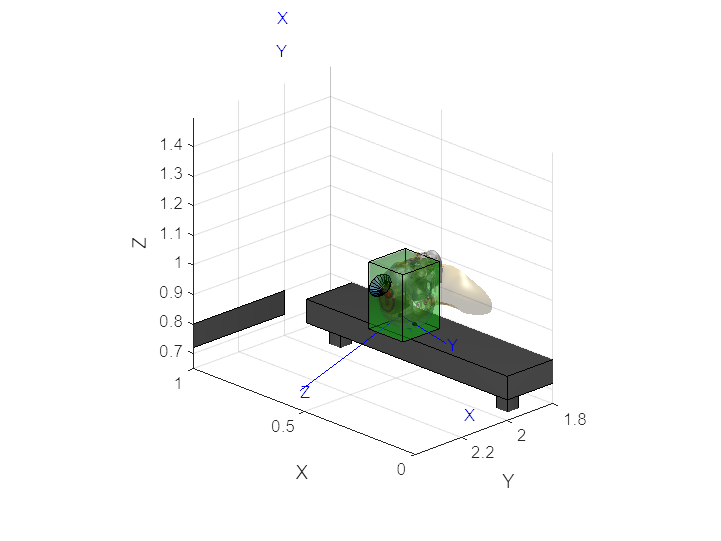

load('F_V_Cone.mat');
cone_scale = 0.04;
p560.tool=transl(0, 0 ,0.2);
cone_figure = [cone_scale 0 0;0 cone_scale 0;0 0 cone_scale]*fvc.vertices';
cone_figure(4,:) = 1;
cone_transform = transl(Ti_U(1), Ti_U(2) + 2*cone_scale/3 + r*cos(pi/4), Ti_U(3)+2*cone_scale/3+r*sin(pi/4)) * trotx(3*pi/4);
cone_figure_pos = cone_transform * cone_figure;
patch('Vertices',cone_figure_pos(1:3,:)','Faces',fvc.faces,'FaceVertexCData',hsv(6),'FaceColor','b','FaceAlpha',0.3);
view([225.693 22.031])

### Movement

In this section, the movement of the trepanation operation is defined. First, the number of steps `n` and the radius of the trepanation `radius` are defined. Then, the position of the tumor center `tumor_center` and the rotation point `rotation_point` are defined using `transl` and `trotx`, `troty`, and `trotz` rotation matrices. A loop runs through `n` steps to calculate the transformation matrix `Ts_trepanation` for each step. Next, the initial and final joint angles for the trepanation movement are calculated using inverse kinematics. The `jtraj` function is used to generate a trajectory `Q_0` to move the robot from the initial joint angles to the joint angles for the first step in `Ts_trepanation`. Then, `p560.ikine6s` is used to calculate joint angles for each step in `Ts_trepanation`, generating a trajectory `Q_1`. Finally, `jtraj` is used again to generate a trajectory `Q_2` to move the robot from the joint angles for the last step in `Ts_trepanation` back to the initial joint angles. The joint angles for the entire trepanation movement are stored in `Q_Trepanation`, which is a concatenation of `Q_0`, `Q_1`, and `Q_2`.

n = 200;
radius = 0.03;
tumor_center = transl(Ti_U(1), Ti_U(2), Ti_U(3));
rotation_point = transl(Ti_U(1), Ti_U(2)+0.017+r*cos(pi/4), Ti_U(3)+ 0.017 + r*sin(pi/4)) * trotx(pi/2) * trotz(pi/2) * trotx(-pi/2) *trotz(-pi/4);
for i=1:n
    Ts_trepanation(:,:,i)= rotation_point*troty(2*pi*i/n)*transl(0, 0, -radius) * trotx(pi/4);
end

INI=p560.fkine(qr);
q_0 = p560.ikine6s(INI,'run'); 
q_1 = p560.ikine6s(Ts_trepanation(:,:,1),'run'); 
t_0=linspace(0,1,200);
Q_0=jtraj(q_0,q_1,t_0);
Q_1 = p560.ikine6s(Ts_trepanation, 'run');

q_2 = p560.ikine6s(Ts_trepanation(:,:,n),'run'); 
q_3 = p560.ikine6s(INI,'run'); 
t_1=linspace(0,1,200);
Q_2=jtraj(q_2,q_3,t_1);
Q_Trepanation = [Q_0; Q_1; Q_2];

### Video

% p560.plot(Q_Trepanation,'view',view([209.976 29.491]), 'zoom',12,'workspace', [-1 0.5 -0.5 0.5 -1 1],'trail','-','jaxes','movie','trepanation_video.mp4')

## Questions

### Biopsy

#### Display in a figure the displacement, velocity and aceleration of the tool i End Efector Reference frame. 

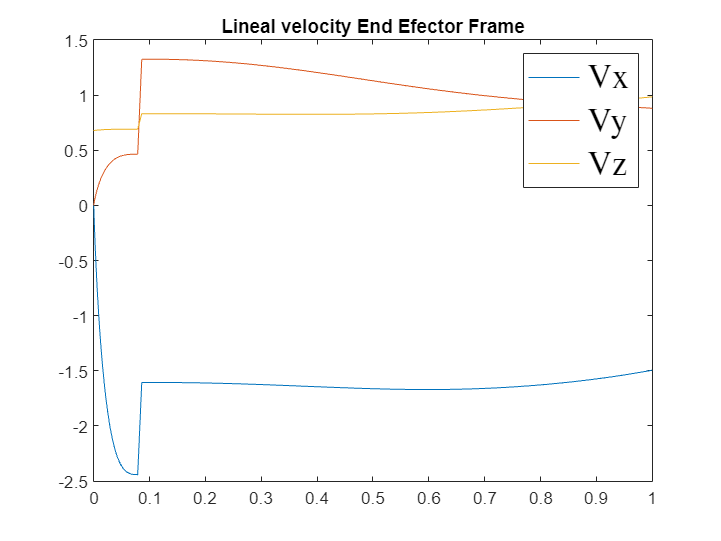

Je=p560.jacobe(QT);
J=p560.jacobe(qr);
thetas_EF = Je*QT';
thetas_WF = J*QT';
t_1=linspace(0,1,130);
S_TPLOT=tpoly(0,1,t_1);
figure
plot(S_TPLOT,thetas_EF(1,:),S_TPLOT, thetas_EF(2,:), S_TPLOT, thetas_EF(3,:))
title('Lineal velocity End Efector Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

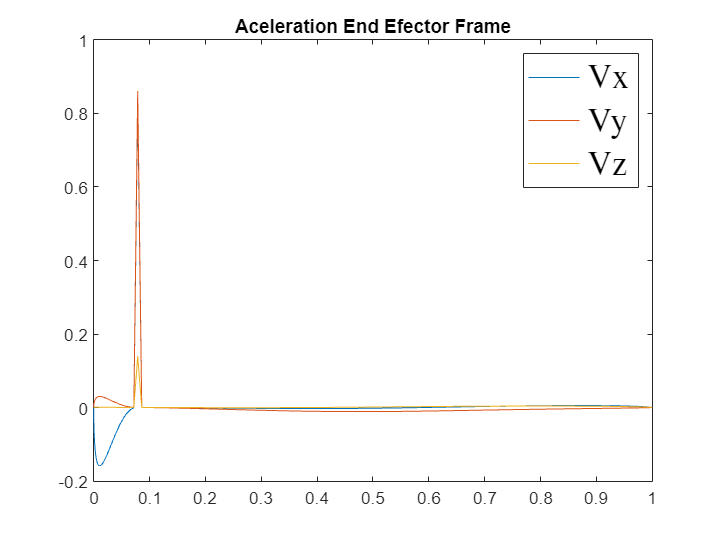

figure
plot(S_TPLOT(1:129),diff(thetas_EF(1,:)),S_TPLOT(1:129), diff(thetas_EF(2,:)), S_TPLOT(1:129), diff(thetas_EF(3,:)))
title('Aceleration End Efector Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

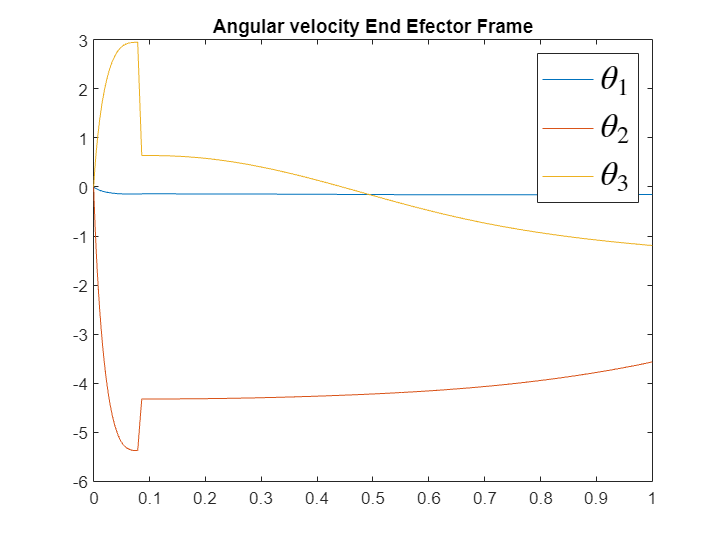

figure
plot(S_TPLOT,thetas_EF(4,:),S_TPLOT, thetas_EF(5,:), S_TPLOT, thetas_EF(6,:))
title('Angular velocity End Efector Frame')
legend ('$\theta_1$','$\theta_2$','$\theta_3$','Interpreter','latex','Fontsize',20)

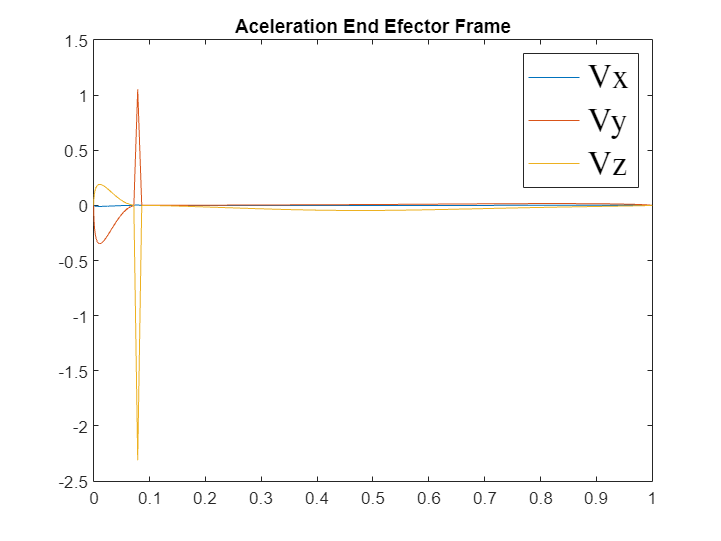

figure
plot(S_TPLOT(1:129),diff(thetas_EF(4,:)),S_TPLOT(1:129), diff(thetas_EF(5,:)), S_TPLOT(1:129), diff(thetas_EF(6,:)))
title('Aceleration End Efector Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

#### How much does the tool enter in the patient brain.

The distance between the end and image 77 in the Dicom Images which is the following:

d = pitch * (112-77)

d = 49

#### What are the speed of the tool in the World Reference Frame

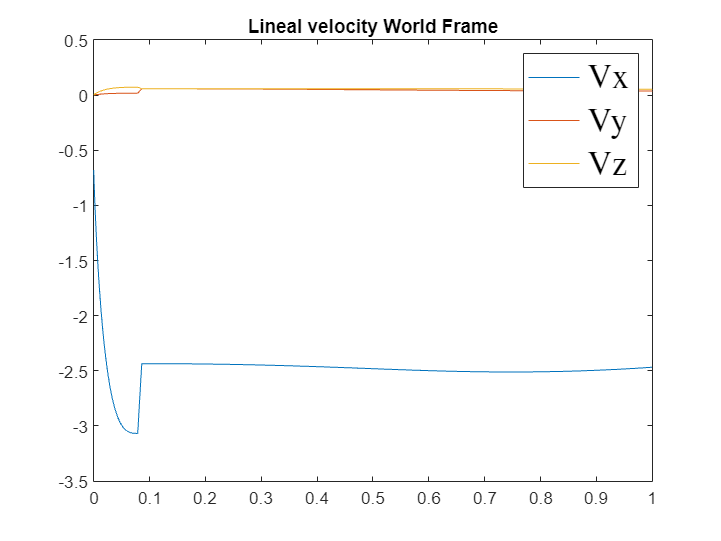

figure
plot(S_TPLOT,thetas_WF(1,:),S_TPLOT, thetas_WF(2,:), S_TPLOT, thetas_WF(3,:))
title('Lineal velocity World Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

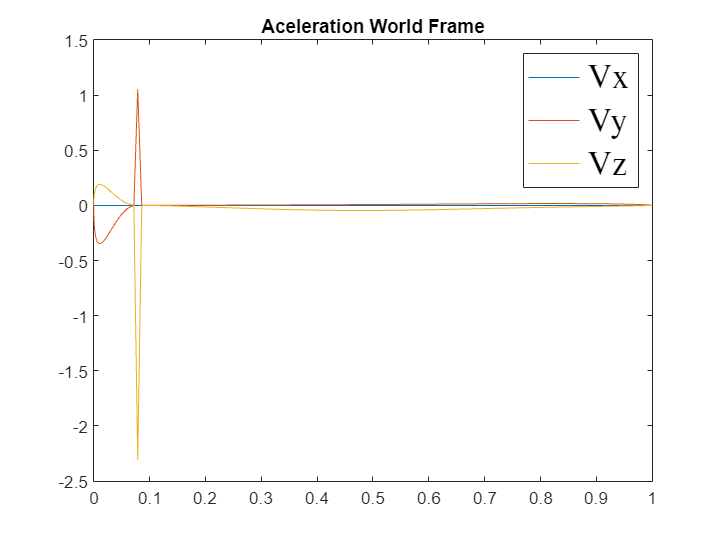

figure
plot(S_TPLOT(1:129),diff(thetas_WF(4,:)),S_TPLOT(1:129), diff(thetas_WF(5,:)), S_TPLOT(1:129), diff(thetas_WF(6,:)))
title('Aceleration World Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

### Burning

#### Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame. 

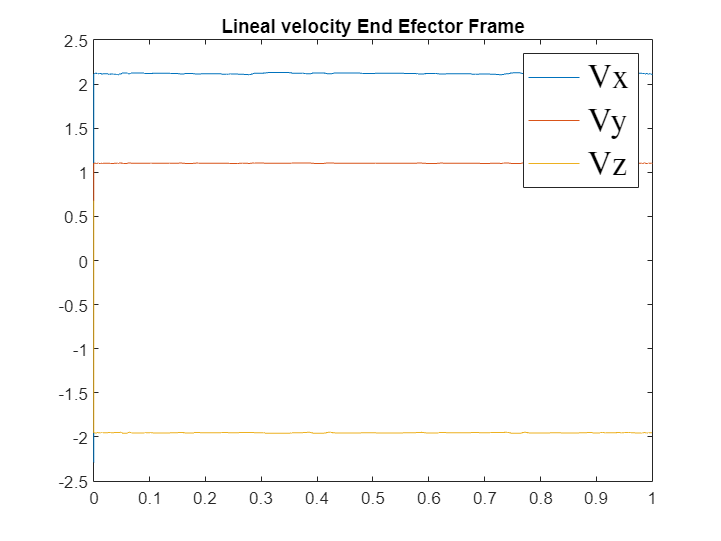

Je=p560.jacobe(Burn);
J=p560.jacobe(qr);
thetas_EF = Je*Burn';
thetas_WF = J*Burn';
t_1=linspace(0,1,7233);
S_TPLOT=tpoly(0,1,t_1);
figure
plot(S_TPLOT,thetas_EF(1,:),S_TPLOT, thetas_EF(2,:), S_TPLOT, thetas_EF(3,:))
title('Lineal velocity End Efector Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

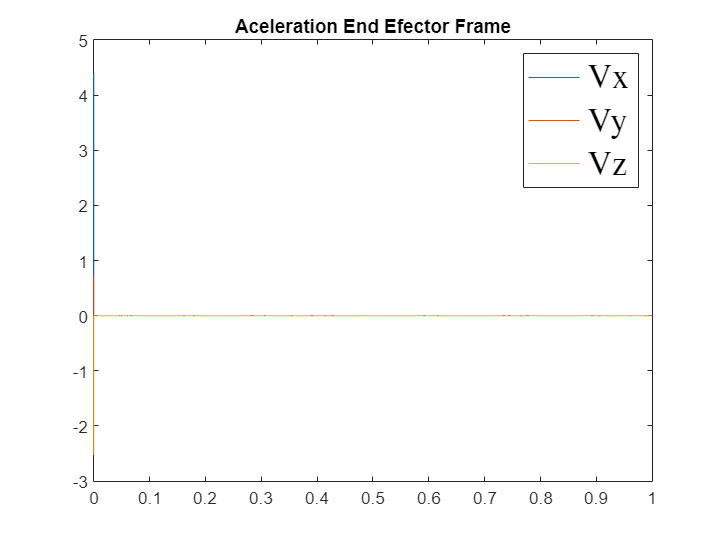

figure
plot(S_TPLOT(1:7232),diff(thetas_EF(1,:)),S_TPLOT(1:7232), diff(thetas_EF(2,:)), S_TPLOT(1:7232), diff(thetas_EF(3,:)))
title('Aceleration End Efector Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

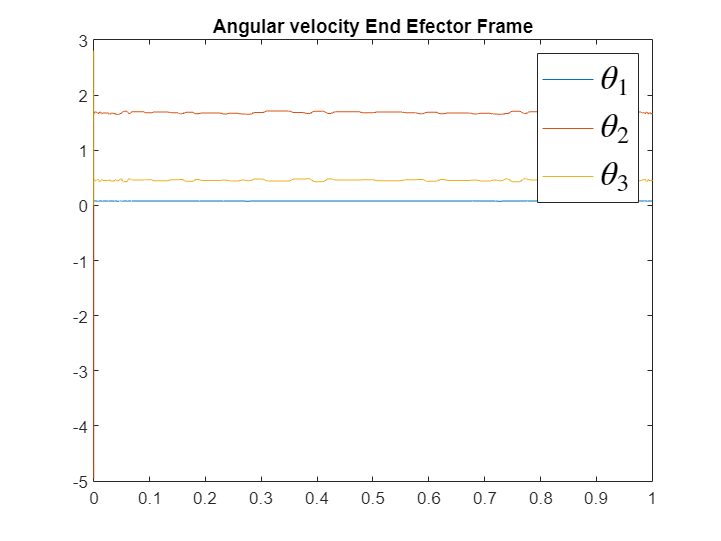

figure
plot(S_TPLOT,thetas_EF(4,:),S_TPLOT, thetas_EF(5,:), S_TPLOT, thetas_EF(6,:))
title('Angular velocity End Efector Frame')
legend ('$\theta_1$','$\theta_2$','$\theta_3$','Interpreter','latex','Fontsize',20)

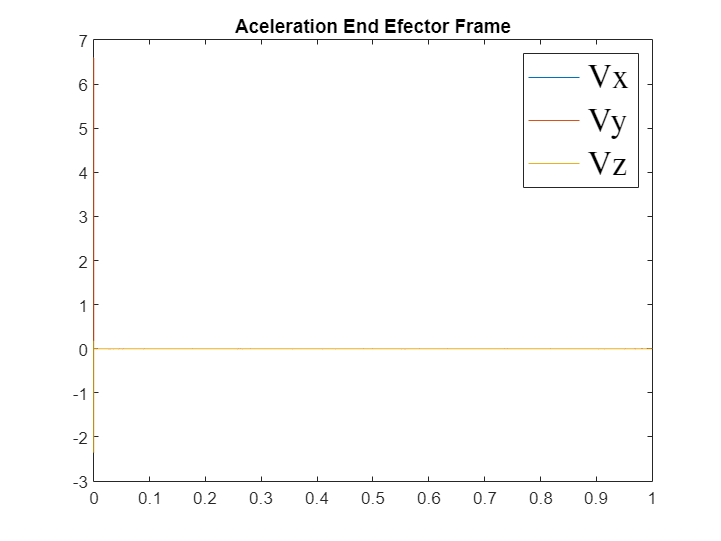

figure
plot(S_TPLOT(1:7232),diff(thetas_EF(4,:)),S_TPLOT(1:7232), diff(thetas_EF(5,:)), S_TPLOT(1:7232), diff(thetas_EF(6,:)))
title('Aceleration End Efector Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

#### How long it takes your burning function to burn the tumor

See burning video lenght.

### Trepanation

#### Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame. 

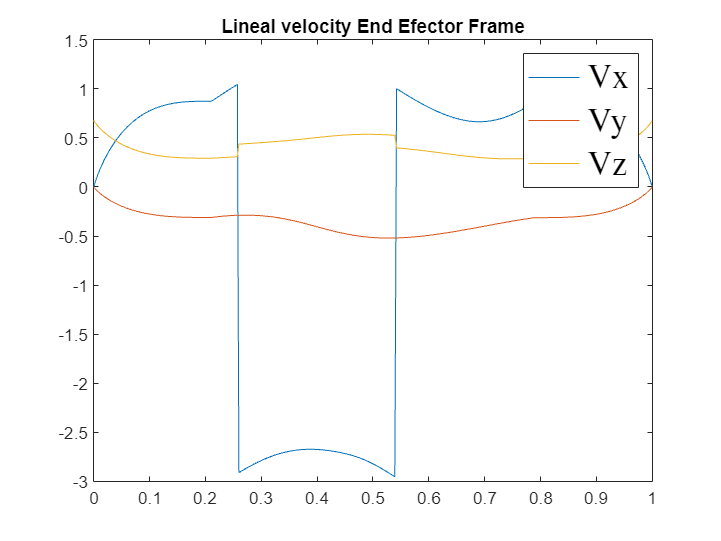

Je=p560.jacobe(Q_Trepanation);
J=p560.jacobe(qr);
thetas_EF = Je*Q_Trepanation';
thetas_WF = J*Q_Trepanation';
t_1=linspace(0,1,600);
S_TPLOT=tpoly(0,1,t_1);
% END EFFECTOR RF respect to axes
figure
plot(S_TPLOT,thetas_EF(1,:),S_TPLOT, thetas_EF(2,:), S_TPLOT, thetas_EF(3,:))
title('Lineal velocity End Efector Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

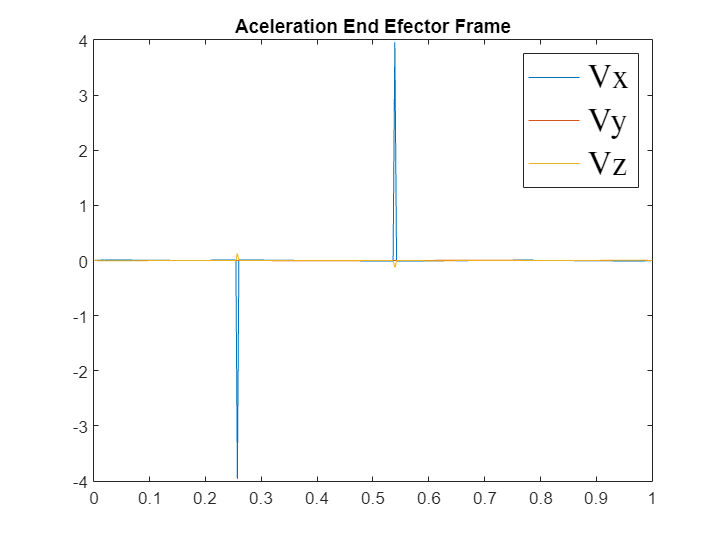

figure
plot(S_TPLOT(1:599),diff(thetas_EF(1,:)),S_TPLOT(1:599), diff(thetas_EF(2,:)), S_TPLOT(1:599), diff(thetas_EF(3,:)))
title('Aceleration End Efector Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

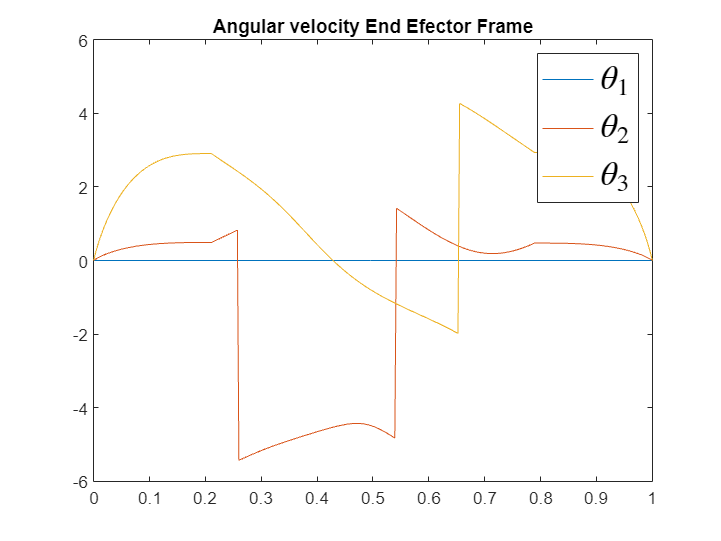

figure
plot(S_TPLOT,thetas_EF(4,:),S_TPLOT, thetas_EF(5,:), S_TPLOT, thetas_EF(6,:))
title('Angular velocity End Efector Frame')
legend ('$\theta_1$','$\theta_2$','$\theta_3$','Interpreter','latex','Fontsize',20)

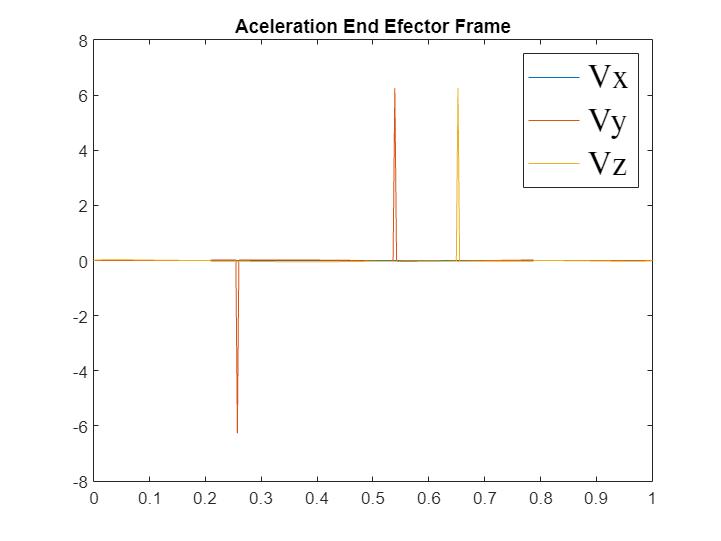

figure
plot(S_TPLOT(1:599),diff(thetas_EF(4,:)),S_TPLOT(1:599), diff(thetas_EF(5,:)), S_TPLOT(1:599), diff(thetas_EF(6,:)))
title('Aceleration End Efector Frame')
legend ('Vx','Vy','Vz','Interpreter','latex','Fontsize',20)

% The prev drastic variations in acceleration and velocity occur due to the robot's entry into and exit from the trepanation operation.

#### Display in a figure the manipulabitlity of the trepanation function either for translation and rotation.

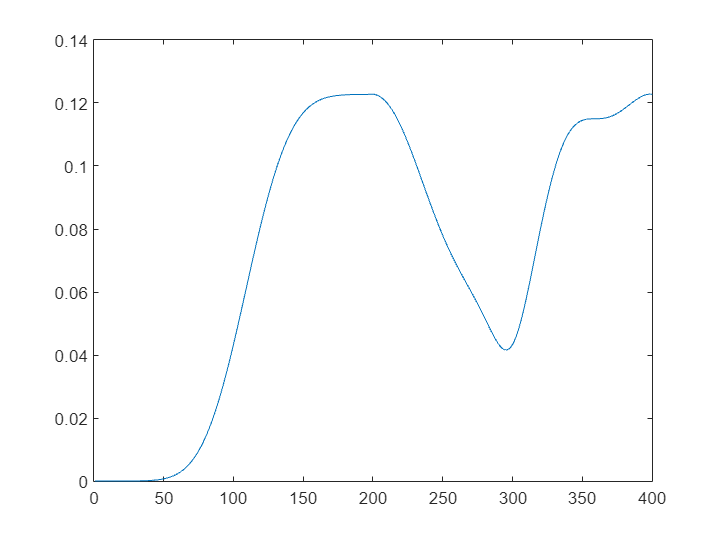

mn= [p560.maniplty(Q_0); p560.maniplty(Q_1)];
figure
plot(mn)

#### Find an alternate robot location for improving your manipulabitity.

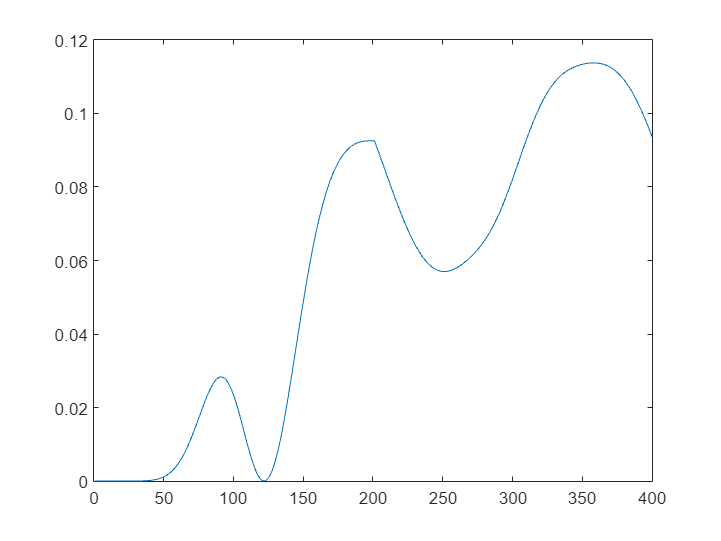

% move it until better manipulability is obtained on average
p560.base=T_Table_U*transl(0.5,2.75,1);

rotation_point = transl(Ti_U(1), Ti_U(2)+0.017+r*cos(pi/4), Ti_U(3)+ 0.017 + r*sin(pi/4)) * trotx(pi/2) * trotz(pi/2) * trotx(-pi/2) *trotz(-pi/4);
for i=1:n
    Ts_trepanation(:,:,i)= rotation_point*troty(2*pi*i/n)*transl(0, 0, -radius) * trotx(pi/4);
end

INI=p560.fkine(qr);
q_0 = p560.ikine6s(INI,'run'); 
q_1 = p560.ikine6s(Ts_trepanation(:,:,1),'run'); 
t_0=linspace(0,1,200);
Q_0=jtraj(q_0,q_1,t_0);
Q_1 = p560.ikine6s(Ts_trepanation, 'run');

mn= [p560.maniplty(Q_0); p560.maniplty(Q_1)];
figure
plot(mn)